# Connect RoadRunner to MATLAB

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;
setenv("NO_PROXY", "localhost");

## Start RoadRunner from MATLAB

Select the RoadRunner installation folder and project folder, then click OK 

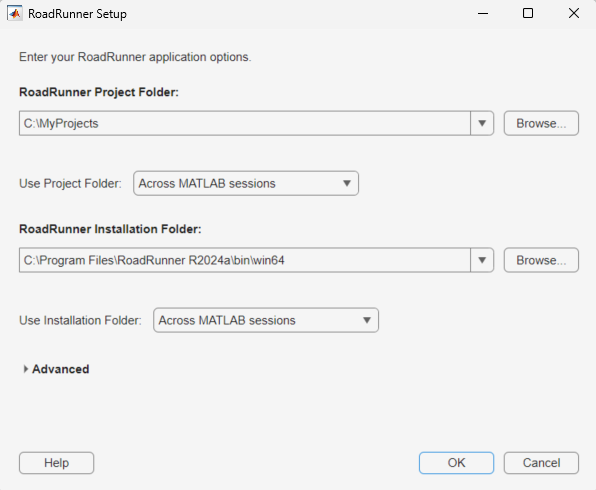

rrApp = roadrunnerSetup(); %Available from R2023b
rrApp 

rrApp =   roadrunner with properties:

    InstallationFolder: 'C:\Program Files\RoadRunner R2024a\bin\win64'
               Version: "R2024a Update 6 (1.8.6.474df36b247)"
             NoDisplay: 0


## Close RoadRunner

rrApp.close(); 

## Reopen the project you just opened in the GUI window

rrApp = roadrunner(); % Project and Install destination opened in the GUI window of roadrunnerSetup(), are automatically specified
% You can also explicitly specify the project folder and installation folder as follows
% lease note that shipping examples are often created in this format, so please rewrite the path to your own path when running the example.
% rrProj = "C:\RR\MyProject";
% rrApp = roadrunner(rrProj,InstallationFolder="C:\Program Files\RoadRunner R2024a\bin\win64"); 

## Open a scene/scenario from a MATLAB function

** Open a scene **

You can open <SceneName>.rrscene in <ProjectFolder>/Scenes/ 

rrApp.openScene("ScenarioBasic"); %Open <ProjectFolder>/Scenes/ScenarioBasic.rrscene

** Open a scenario **

You can open <ScenarioName>.rrscenario in <ProjectFolder>/Scenarios 

rrApp.openScenario("TrajectoryCutIn"); %Open <ProjectFolder>/Scenarios/TrajectoryCutIn.rrscenario

** Run a scenario **

Run a scenario with the function below 

rrSim = rrApp.createSimulation();
set(rrSim,"Logging","on");

% Start simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end 

## Advanced: Get the RoadRunner execution log

You can get the driving trajectory and speed data of each vehicle 

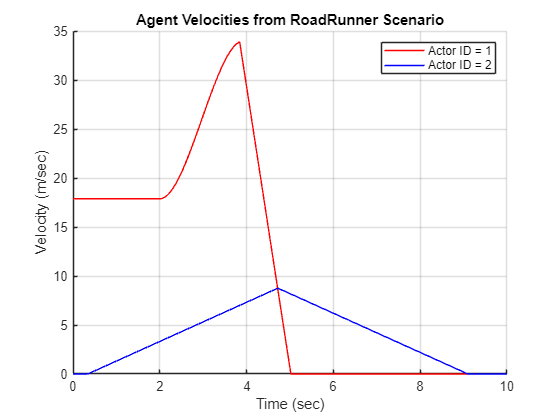

% Turn on the setting to obtain logs
set(rrSim,"Logging","on");

% Run simulation
set(rrSim,"SimulationCommand","Start");
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

% Get log
rrLog = get(rrSim,"SimulationLog");

% Get vehicle speed
velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Get the speed of Actor1
velocityAgent2 = get(rrLog,'Velocity','ActorID',2); % Get the speed of Actor2
time = [velocityAgent1.Time];% Get the time of Actor1

% Plot vehicle speed
helperPlotVelocity(time, velocityAgent1, velocityAgent2);

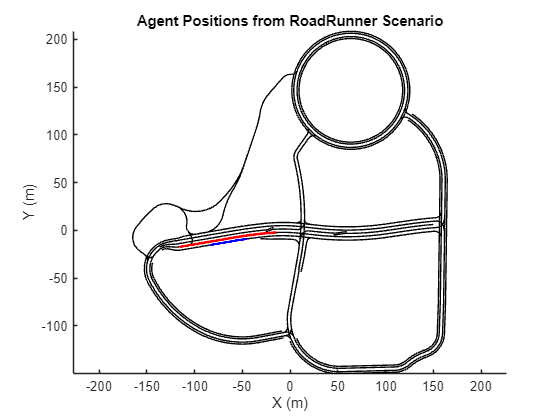


% Plot the vehicle trajectory and map
helperPlotTrajectoryMap(rrSim, rrLog); 

## Reference

** Run a scenario (R2024a and later) **

% rrApp.simulateScenario("IsBlocking", true); % R2024a以降実行可能 

function helperPlotVelocity(time, velocityAgent1, velocityAgent2)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);

    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    figure
    hold on
    plot(time,velMagAgent1,"r")
    plot(time,velMagAgent2,"b")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend("Actor ID = 1","Actor ID = 2")
end
function helperPlotTrajectoryMap(rrSim, rrLog)
    hdMap = get(rrSim, "Map");
    lanes = hdMap.Lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on
    for i = 1:numel(lanes)
        control_points = lanes(i).Geometry;
        x_coordinates = control_points(:,1);
        y_coordinates = control_points(:,2);
        plot(x_coordinates, y_coordinates, 'black');
    end
    axis equal
    
    
    % Extract the positions of the vehicles and plot them on the lanes.
    poseActor1 = rrLog.get('Pose','ActorID',1);
    positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
    positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);
    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2)
    
    poseActor2 = rrLog.get('Pose','ActorID',2);
    positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
    positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2)
    
    title("Agent Positions from RoadRunner Scenario")
    ylabel("Y (m)")
    xlabel("X (m)")
end